# 12주차 과제 — 상태공간 해석

**제어시스템설계** · 충남대학교 자율운항시스템공학과

문제는 **세 개**입니다.

- **1. 몸풀기** (쉬움 · 수업 중 10분 · 30점) — 고유값과 모드 읽기

- **2. 기본** (중간 · 40분 · 70점) — 가제어성과 가관측성 판정

- **3. 도전** (선택 · 가산점 10점) — 숨은 모드 찾기

**3번은 선택입니다.** 1번과 2번만 해도 만점입니다.

clc; close all;
s = tf('s');

## 1. 몸풀기 — 고유값과 모드

**강의노트 3~5절을 그대로 보면 됩니다.**

아래 시스템의 고유값과 고유벡터를 구하고, 어느 모드가 더 오래 남는지 답하십시오.


$$A = \left[\begin{array}{cc} -3 & 1\\ 0 & -0.5\end{array}\right]$$


힌트 — `eig(A)` 를 출력을 두 개 받아 부르면 `[V, D] = eig(A)` 로 고유벡터와 고유값을 함께 얻습니다.

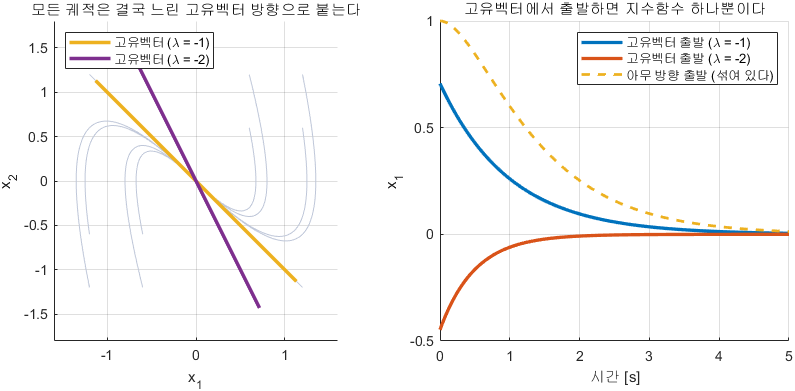

고유벡터 위에서 출발하면 직선, 아니면 휜다

**그림 파일** `w12_modes.png` — `make_figures.m` 의 `fig_modes` · 다시 만들려면 `make_figures('w12_modes')`

## 1-1. 고유값 구하기

`TODO` 한 줄만 채우면 됩니다.

A1 = [-3 1; 0 -0.5];

lam = NaN;
% TODO : lam = eig(A1);  로 바꾸십시오

if isnan(lam)
    fprintf('  (아직 안 채웠습니다)\n');
else
    fprintf('  고유값 : %s\n', mat2str(round(lam.', 4)));
    fprintf('  느린 모드의 시정수 : %.3f s\n', 1/min(abs(real(lam))));
end

## 1-2. 답할 것 (세 문장이면 됩니다)

- 이 시스템은 안정합니까? 그렇게 판단한 근거는 무엇입니까?

- 두 모드 중 **오래 남는 쪽**은 어느 것입니까? 왜 그렇습니까?

- 초기조건에서 출발한 응답의 꼬리는 어느 모드가 정합니까?

## 2. 기본 — 가제어성과 가관측성

**강의노트 7~12절을 보면 됩니다.**

아래 세 시스템에 대해 가제어성과 가관측성을 판정하십시오.


$$A = \left[\begin{array}{cc} -1 & 0\\ 0 & -4\end{array}\right]$$


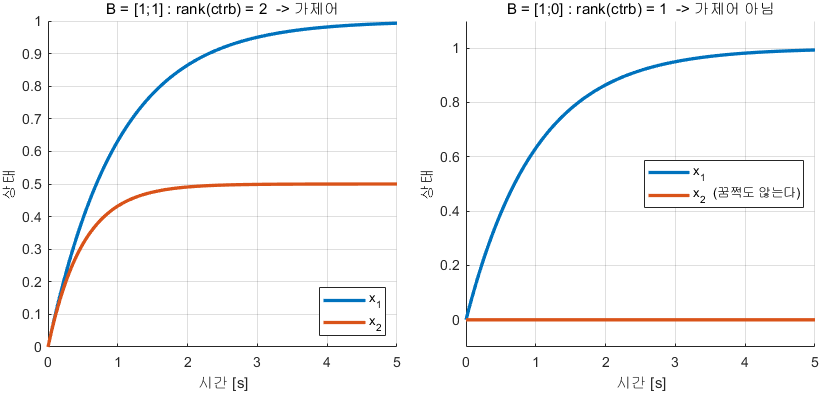

입력이 못 미는 상태는 꿈쩍도 하지 않는다

**그림 파일** `w12_ctrb.png` — `make_figures.m` 의 `fig_ctrb` · 다시 만들려면 `make_figures('w12_ctrb')`

## 2-1. 판정표 채우기

`TODO` 두 줄만 채우면 됩니다.

A2 = [-1 0; 0 -4];
cases = { '(a)', [1;1], [1 1]
          '(b)', [1;0], [1 1]
          '(c)', [1;1], [0 1] };

fprintf('   경우   rank(ctrb)   rank(obsv)   가제어   가관측\n');
fprintf('   ----   ----------   ----------   ------   ------\n');
for k = 1:3
    B = cases{k,2};  C = cases{k,3};

    rc = NaN;
    ro = NaN;
    % TODO : rc = rank(ctrb(A2, B));   로 바꾸십시오
    % TODO : ro = rank(obsv(A2, C));   로 바꾸십시오

    if isnan(rc) || isnan(ro)
        fprintf('   %4s   (아직 안 채움)\n', cases{k,1});
        continue
    end
    fprintf('   %4s   %10d   %10d   %6s   %6s\n', cases{k,1}, rc, ro, ...
            hw_yn(rc == 2), hw_yn(ro == 2));
end

## 2-2. 확인 — 실제 응답으로

판정이 맞는지 눈으로 봅니다. **이 절은 코드가 다 되어 있습니다.** 실행한 뒤 그림을 보십시오.

t = (0:0.01:5)';
u = ones(size(t));

tiledlayout(1, 3, 'TileSpacing', 'compact');
for k = 1:3
    B = cases{k,2};
    [~, ~, X] = lsim(ss(A2, B, eye(2), [0;0]), u, t, [0;0]);
    nexttile
    plot(t, X(:,1), 'LineWidth', 2.2); hold on; grid on;
    plot(t, X(:,2), 'LineWidth', 2.2);
    xlabel('시간 [s]'); ylabel('상태'); ylim([-0.1 1.1]);
    legend('x_1', 'x_2', 'Location', 'southeast');
    title(sprintf('%s  B = %s', cases{k,1}, mat2str(B.')));
end

## 2-3. 답할 것 (네 문장이면 됩니다)

- (b) 에서 가제어가 깨진 이유를 **물리적으로** 설명하십시오

- (c) 에서 가관측이 깨졌습니까? 판정 결과와 그 이유를 쓰십시오

- 이 중 **13주차 극배치를 할 수 있는** 경우는 어느 것입니까?

- 이 중 **14주차 관측기를 만들 수 있는** 경우는 어느 것입니까?

## 3. 도전 (선택) — 숨은 모드 찾기

**강의노트 12-1절을 보면 됩니다.** 안 해도 감점 없습니다.

아래 시스템은 상태가 세 개입니다.


$$A = \left[\begin{array}{ccc} -1 & 0 & 0\\ 0 & 2 & 0\\ 0 & 0 & -5\end{array}\right], \quad B = \left[\begin{array}{c} 1\\ 0\\ 1\end{array}\right], \quad C = \left[\begin{array}{ccc} 1 & 1 & 1\end{array}\right]$$


두 번째 고유값이 $+2$ 로 **불안정**하다는 점에 주목하십시오.

할 일

- 고유값을 구하고, 전달함수의 극점과 **개수를 비교**하십시오

- `minreal` 로 줄여 보고 상태가 몇 개가 되는지 보십시오

- 계단응답을 그려 보십시오. 발산합니까?

- **가장 중요한 질문** — 계단응답만 보고 이 시스템을 안전하다고 판단해도 됩니까? 왜 그렇습니까?

A3 = [-1 0 0; 0 2 0; 0 0 -5];
B3 = [1; 0; 1];
C3 = [1 1 1];
sys3 = ss(A3, B3, C3, 0);

fprintf('\n=== 3. 도전 문제 ===\n');
fprintf('  고유값 : %s\n', mat2str(round(eig(A3).', 3)));
fprintf('  (여기서부터 직접 해 보십시오)\n');

## 4. 제출 방법

- 이 파일을 `W12_HW_학번_이름.mlx` 로 저장해 제출하십시오

- `TODO` 를 채운 코드와 **실행 결과(그림 포함)** 가 함께 보여야 합니다

- 답할 것은 각 문제 아래에 **글로 적으십시오**. 한두 문장이면 충분합니다

- 도전 문제를 안 했으면 그 절은 그대로 두십시오

## 5. 채점 기준

- **1. 몸풀기** 30점 — 고유값을 구했는가, 어느 모드가 오래 남는지 맞혔는가

- **2. 기본** 70점 — 판정표를 다 채웠는가, 네 질문에 답했는가

- **3. 도전** 가산점 10점 — 숨은 모드를 찾아내고 위험성을 설명했는가

감점 항목 (세 개뿐입니다)

- `rank` 를 씌우지 않고 `ctrb` 결과만 보고 판정한 경우

- 계단응답이 멀쩡하다는 이유로 안전하다고 결론 내린 경우

- 그림에 축 이름이나 범례가 없는 경우

---------------------------------------------------------------

function s = hw_yn(tf_)
if tf_, s = '예'; else, s = '아니오'; end
end